# Shaft Design

Malik Labban, Jet Burginger, Isaac Coello Dantus, Allistair Pocock, Anthony Jakubczyk

clear all
close all

### Shaft Specs

Nf = 5;     % Shaft without stress concentration
Ny = 3;     % Shaft without stress concentration
Nf_fillet = 2.5;% Design factor of fillet with stress concentrations
Ny_fillet = 2;

### Material

E = 29000e3;
rho = 0.284; %lb/in^3

### External Loadings

K = 3;     % Possible load multiplier
Ti = 38.6;  % ft-lbs
RPM = 200;  % RPM

### Gear Specs

globe.phi_n = deg2rad(20); % deg       (normal pressure angle)
globe.P = 12;     % teeth/in  (normal diametral pitch)
globe.psi = deg2rad(0);   % deg       (helix angle)
N1 = 16;    % # teeth 
N2 = 72;    % # teeth
N3 = 16;    % # teeth
N4 = 72;
T2 = Ti*N1/N2;
T3 = T2*N3/N4;
%gear# = Gear(globe,name,#teeth,torque on shaft,RPM,pos)

### Shaft Opt

Input Shaft

syms x D
gear1 = Gear(globe,'G1',N1,Ti,RPM,6.75);
bearing1 = bearing('A',4.5);
bearing2 = bearing('B',8);
input1 = [0,D; ...   % shaft diamter breakdown
            4,D;
            5,D;
            5.75,D*1.2;
            7.75,D;
            8.5,D*0.9];
geo1 = geo(9.5); % length of shaft
geo1.input = input1;
shaftA = shaft(geo1,'Input Shaft',1000);
shaftA.gear = gear1;
shaftA.bearing = [bearing1,bearing2];
shaftA.presolve(K);
shaftA.initialD(Nf,Ny,Nf_fillet,Ny_fillet,'no');

$$nfmin = 5.1887$$

$$nymin = 3.0272$$

Minimum diameter for Yielding, 2.0500, for Fatigue, 3.9500.
Initial Diameter 3.9500



shaftA.optimize();

Iteration for fillet radius at point 4.000 is complete, Radi of fillet is 0.000 
This fillet radi had an r/d ratio of 0.000 and h/r of NaN

Iteration for fillet radius at point 5.000 is complete, Radi of fillet is 0.000 
This fillet radi had an r/d ratio of 0.000 and h/r of NaN

Iteration for fillet radius at point 5.750 is complete, Radi of fillet is 1.270 
This fillet radi had an r/d ratio of 0.321 and h/r of 0.311

Iteration for fillet radius at point 7.750 is complete, Radi of fillet is 0.020 
This fillet radi had an r/d ratio of 0.005 and h/r of 20.000

Iteration for fillet radius at point 8.500 is complete, Radi of fillet is 0.010 
This fillet radi had an r/d ratio of 0.003 and h/r of 20.000

Final Diameter 3.9500
Final Weight: 35.4634

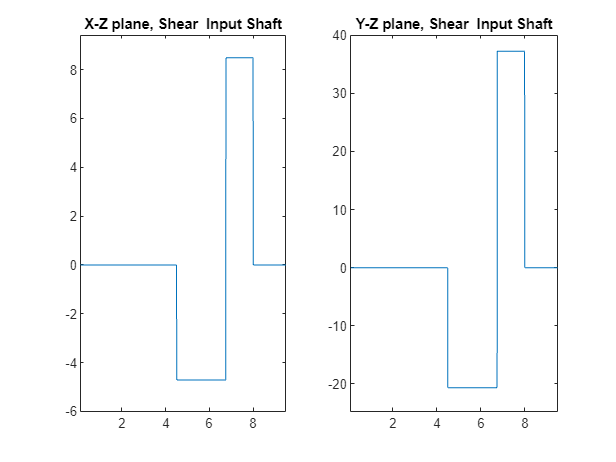

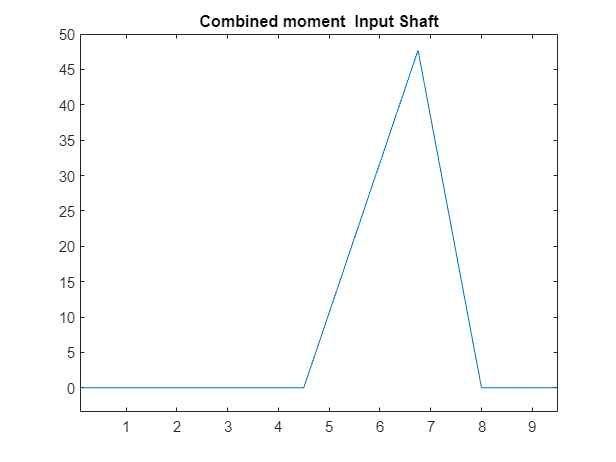

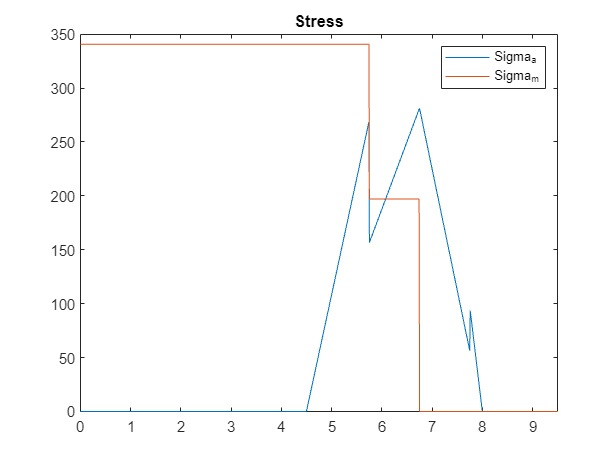

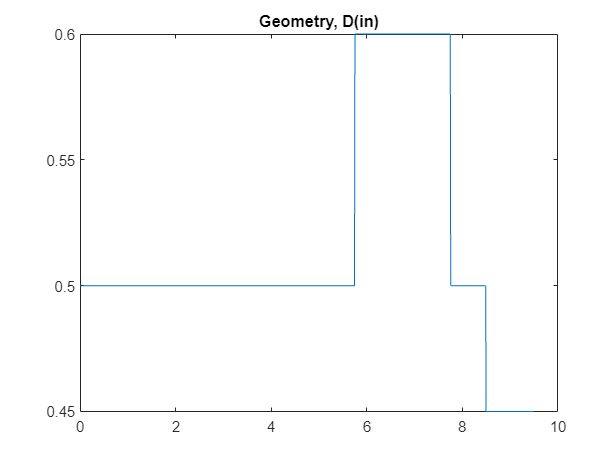

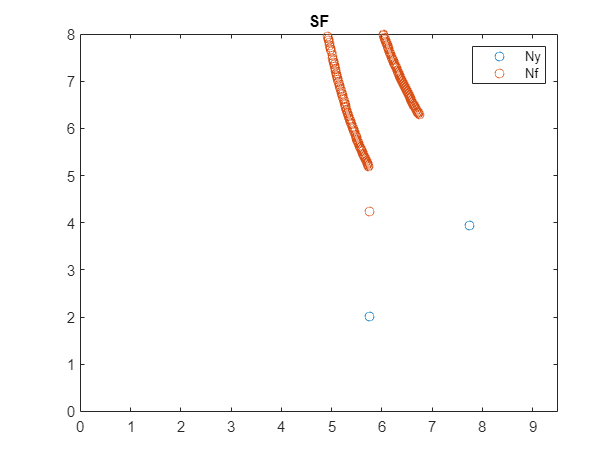

shaftA.plot

### Shaft Opt

Middle Shaft

syms x D
gear2 = Gear(globe,'G2',N2,T2,RPM,2.75);
gear3 = Gear(globe,'G3',N3,Ti,RPM,8.5);
bearing3 = bearing('C',0.5);
bearing4 = bearing('D',10.5);
input2 = [0,D*0.75; ...
            1.75,D;
            3.75,D*1.2;
            7.75,D;
            9.25,D*0.9];
geo2 = geo(11);
geo2.input = input2;
shaftB = shaft(geo2,'Middle Shaft',1000);
shaftB.gear = [gear2,gear3];
shaftB.bearing = [bearing3,bearing4];
shaftB.presolve(K);
shaftB.initialD(Nf,Ny,Nf_fillet,Ny_fillet,'no');

$$nfmin = 5.0307$$

$$nymin = 3.0405$$

Minimum diameter for Yielding, 2.7000, for Fatigue, 5.0000.
Initial Diameter 5.0000



shaftB.optimize();

Iteration for fillet radius at point 1.750 is complete, Radi of fillet is 0.057 
This fillet radi had an r/d ratio of 0.015 and h/r of 11.257

Iteration for fillet radius at point 3.750 is complete, Radi of fillet is 0.051 
This fillet radi had an r/d ratio of 0.010 and h/r of 10.148

Iteration for fillet radius at point 7.750 is complete, Radi of fillet is 1.851 
This fillet radi had an r/d ratio of 0.359 and h/r of 0.278

Iteration for fillet radius at point 9.250 is complete, Radi of fillet is 0.788 
This fillet radi had an r/d ratio of 0.170 and h/r of 0.327

Final Diameter 5.1500
Final Weight: 68.9881

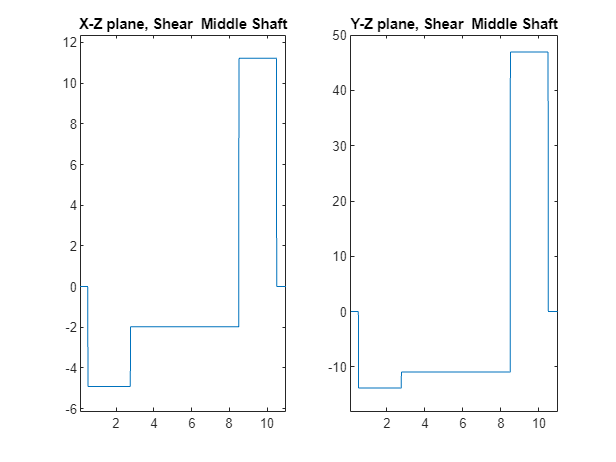

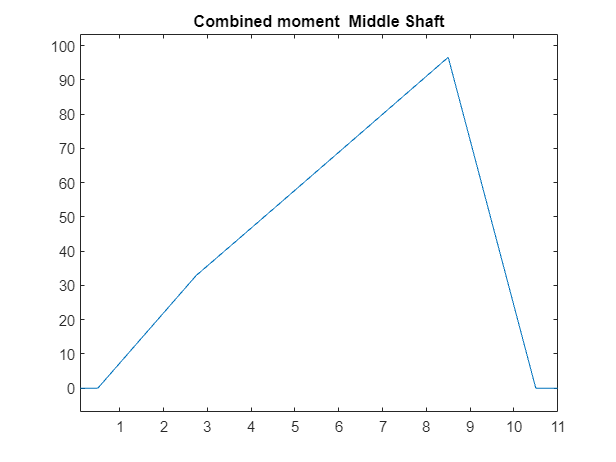

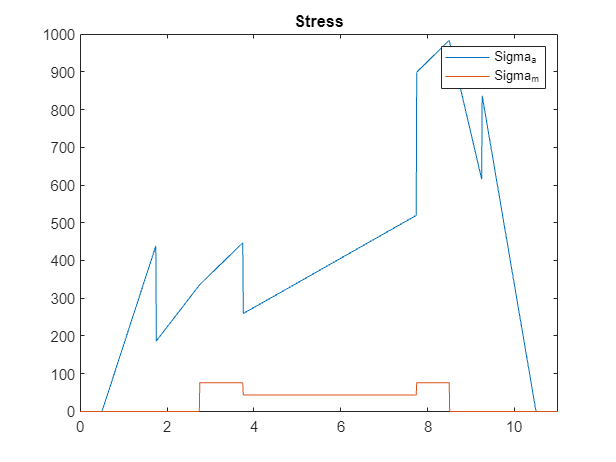

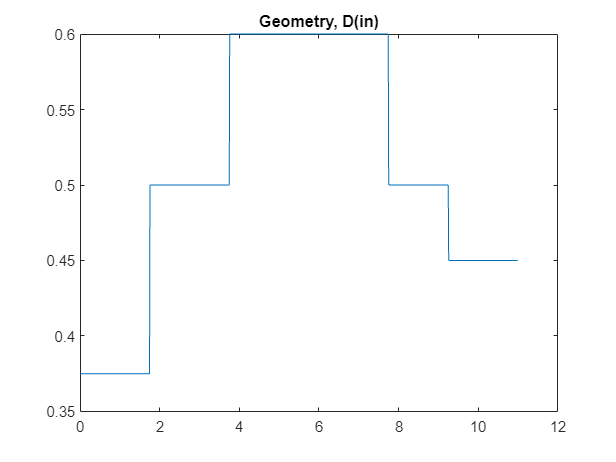

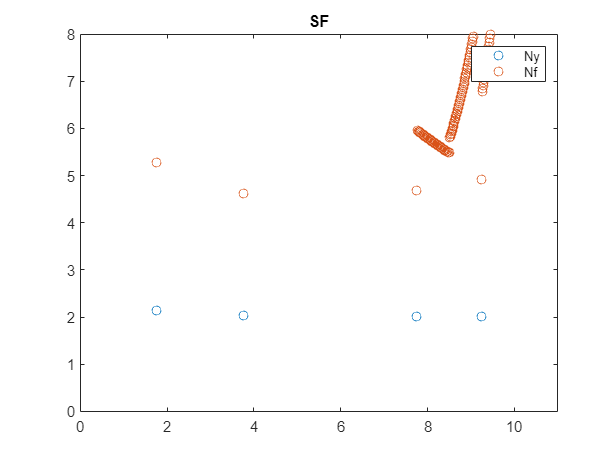

shaftB.plot

### Shaft Opt

Output Shaft

syms x D
gear4 = Gear(globe,'G4',N4,T3,RPM,4.5);
bearing5 = bearing('G',2.5);
bearing6 = bearing('H',6.125);
input3 = [0,D*.9; ...   % shaft diamter breakdown
            2,D;
            3,D;
            3.75,D*1.2;
            5.25,D;
            5.75,D*0.9];
geo3 = geo(6.5);
geo3.input = input3;
shaftC = shaft(geo3,'Output Shaft',1000);
shaftC.gear = gear4;
shaftC.bearing = [bearing5,bearing6];
shaftC.presolve(K);
shaftC.initialD(Nf,Ny,Nf_fillet,Ny_fillet,'no');

$$nfmin = 5.5195$$

$$nymin = 3.3829$$

Minimum diameter for Yielding, 0.8000, for Fatigue, 1.4000.
Initial Diameter 1.4000



shaftC.optimize();

Iteration for fillet radius at point 2.000 is complete, Radi of fillet is 0.079 
This fillet radi had an r/d ratio of 0.057 and h/r of 0.983

Iteration for fillet radius at point 3.000 is complete, Radi of fillet is 0.000 
This fillet radi had an r/d ratio of 0.000 and h/r of NaN

Iteration for fillet radius at point 3.750 is complete, Radi of fillet is 0.033 
This fillet radi had an r/d ratio of 0.021 and h/r of 4.733

Iteration for fillet radius at point 5.250 is complete, Radi of fillet is 0.008 
This fillet radi had an r/d ratio of 0.005 and h/r of 20.000

Iteration for fillet radius at point 5.750 is complete, Radi of fillet is 0.004 
This fillet radi had an r/d ratio of 0.003 and h/r of 20.000

Final Diameter 1.5500
Final Weight: 3.5548

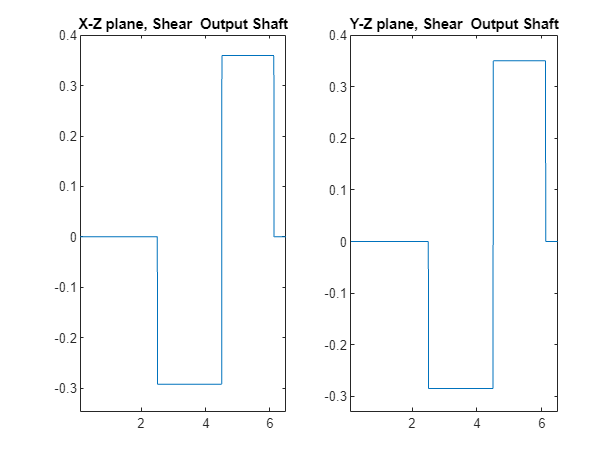

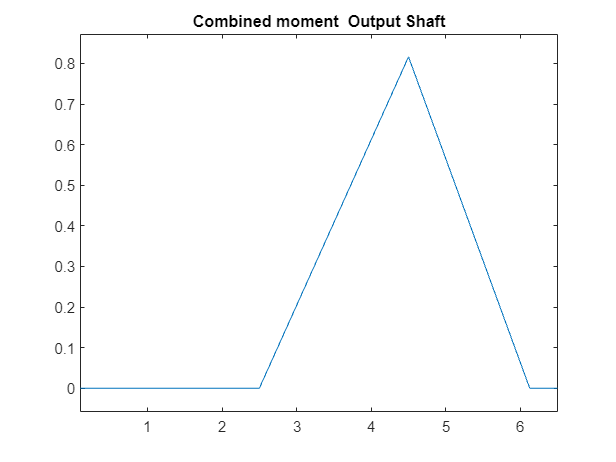

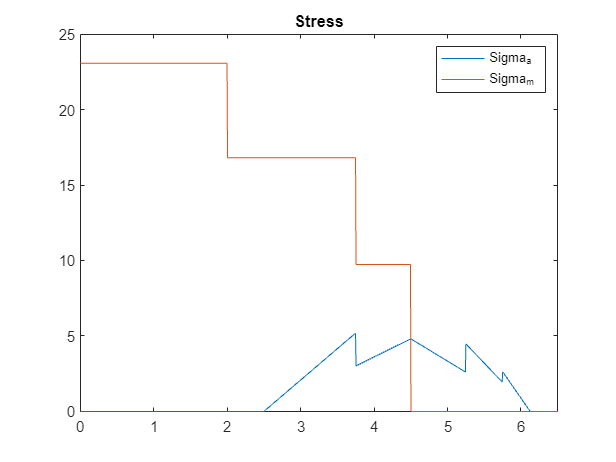

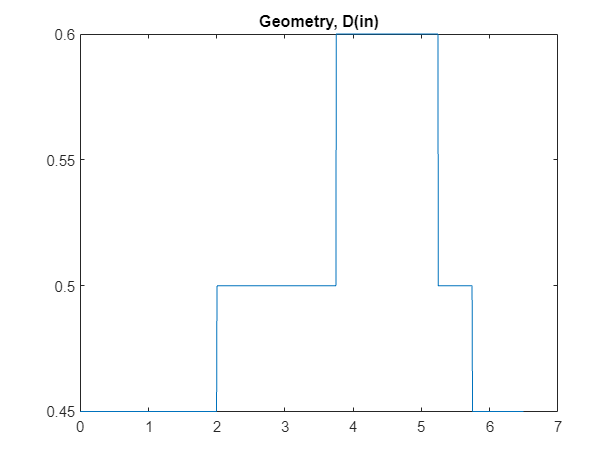

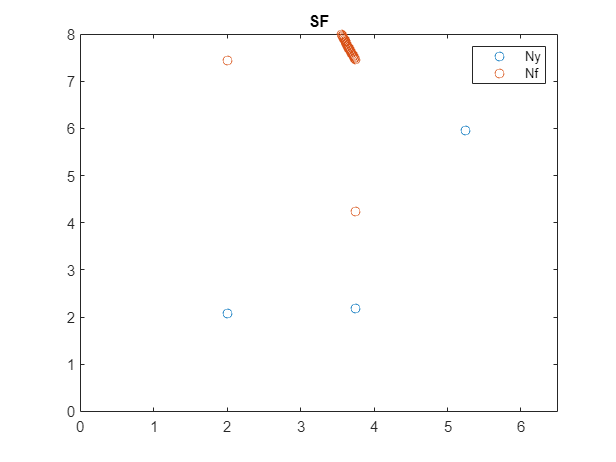

shaftC.plot